Project 1: Getting to know Matlab

c = -1.09;
d = 0.02;

%initialize 
x = zeros(1,22);
y = zeros(1,22);
N = 1:22;

%initialize starting points
x(1) = 0.1

x =     0.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y(1) = 0.1

y =     0.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


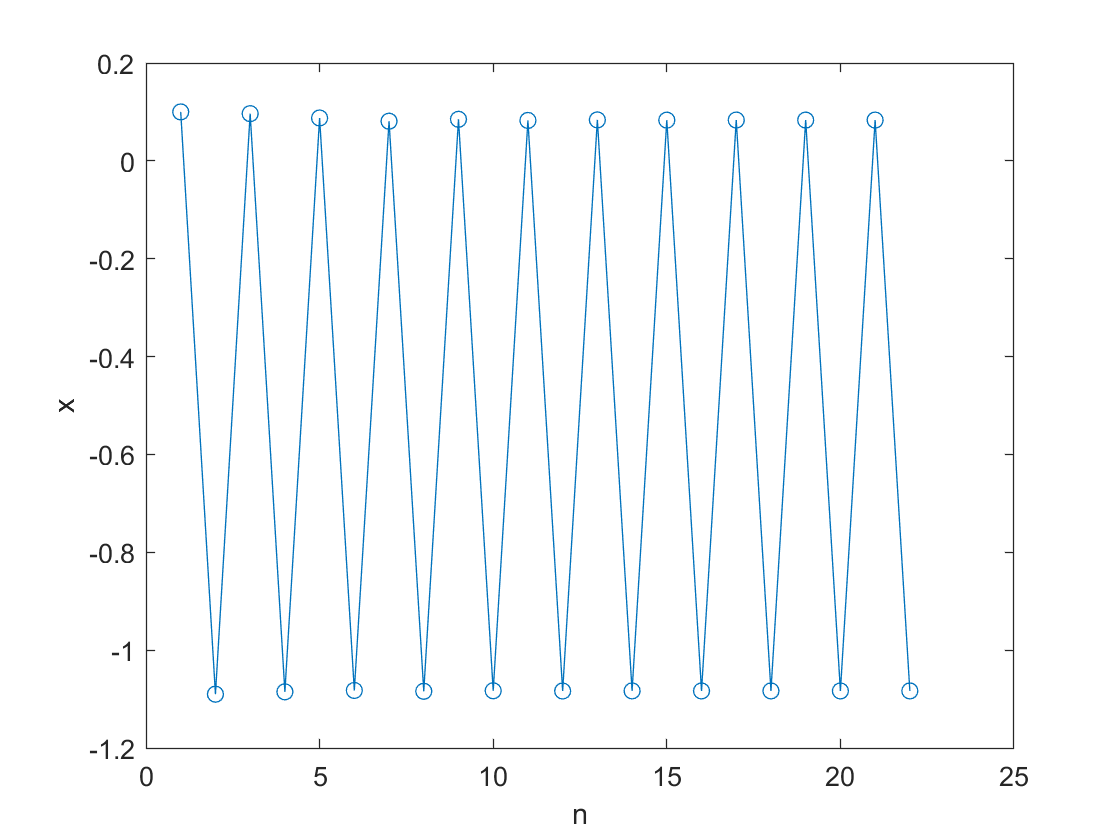


%part a
for n=1:21
    x(n+1) = x(n)^2 - y(n)^2 + c;
    y(n+1) = 2 * x(n) * y(n) + d; 
end 

%part b
figure;
plot(x, '-o')
xlabel('n')
ylabel('x')

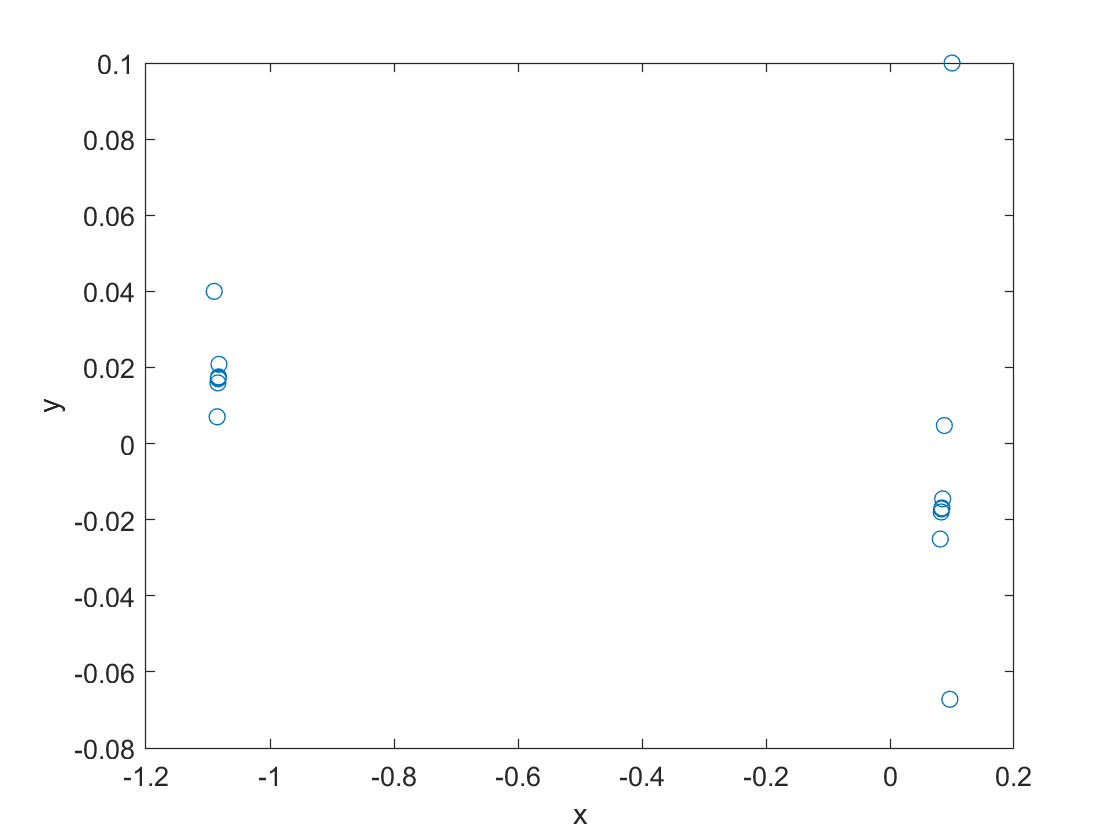


%part c
figure;
plot(x, y, 'o')
xlabel('x')
ylabel('y')

%part d
r = -2 + (2 + 2).*rand(1,100);

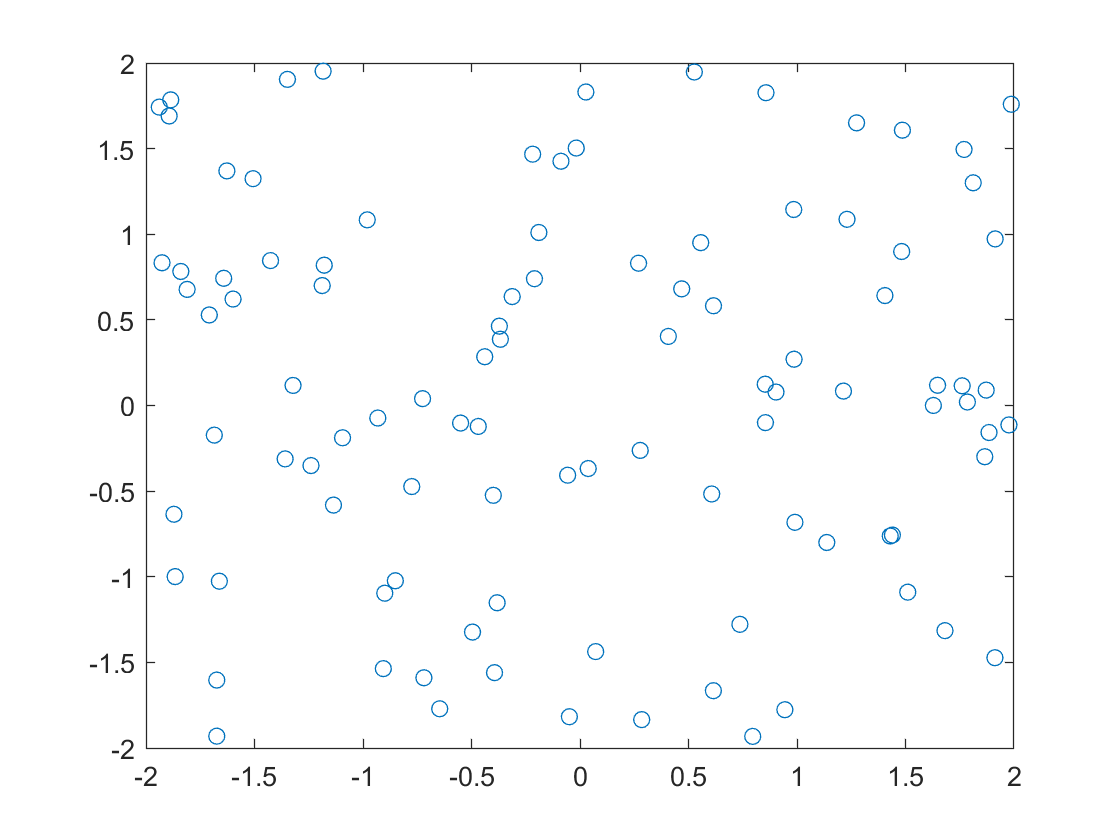

%part e 
NStartingPoints = 100;
x = -2 + (2 + 2).*rand(1,NStartingPoints);
y = -2 + (2 + 2).*rand(1,NStartingPoints);
figure;
plot(x, y, 'o');

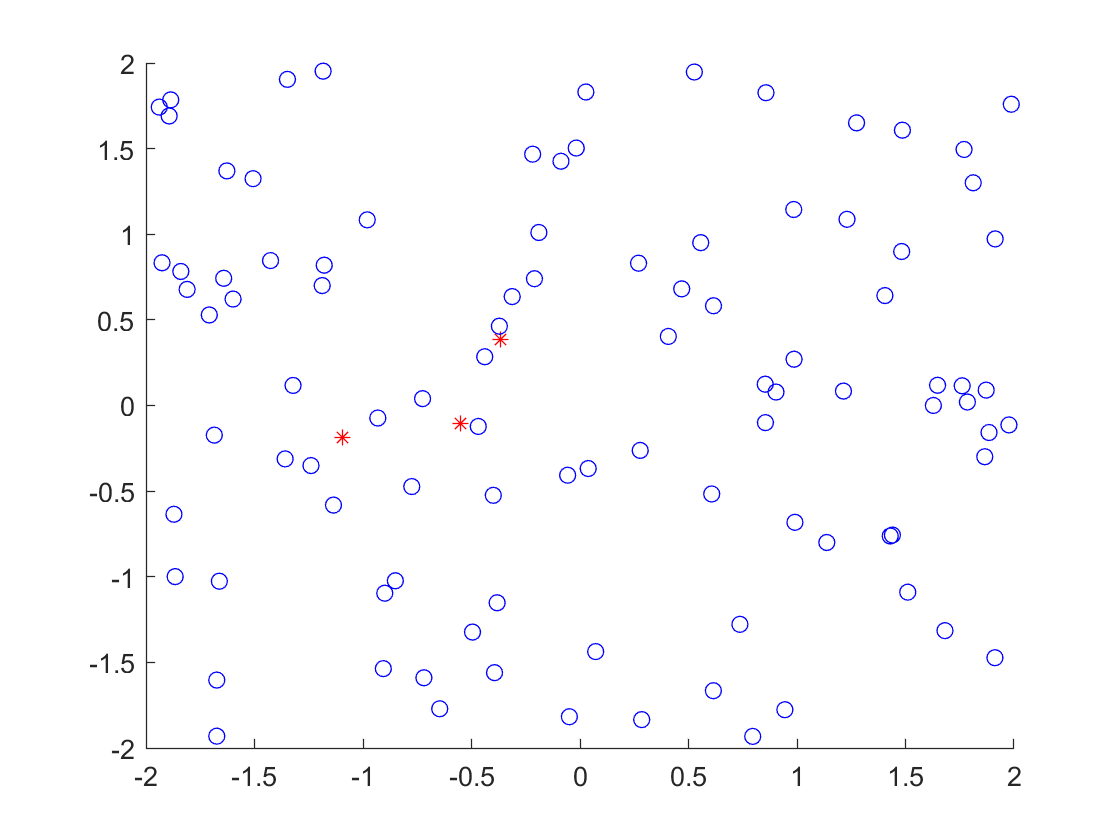


%part f
xx_22 = zeros(1,NStartingPoints);
yy_22 = zeros(1,NStartingPoints);

for i = 1:NStartingPoints
    xx(1) = x(i);
    yy(1) = y(i);
    for n=1:21
        xx(n+1) = xx(n)^2 - yy(n)^2 + c;
        yy(n+1) = 2 * xx(n) * yy(n) + d;
    end 
    xx_22(i) = xx(22);
    yy_22(i) = yy(22);
end

figure; hold on;
for i = 1:NStartingPoints
    if xx_22(i) > 2 | xx_22(i) < -2 | yy_22(i) > 2 | yy_22(i) < -2
        plot(x(i), y(i), "*r")
    else
        plot(x(i), y(i), "ob")
    end 
end
hold off;

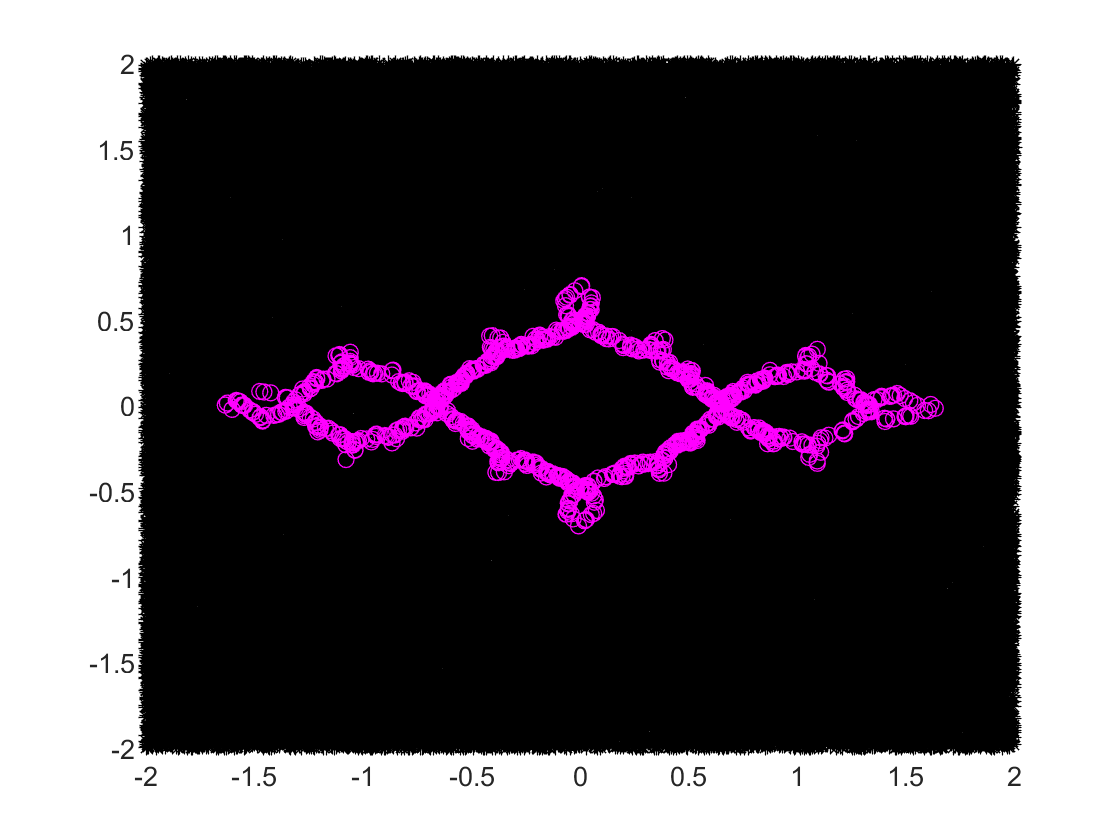

%part g
NStartingPoints = 1e5;
x = -2 + (2 + 2).*rand(1,NStartingPoints);
y = -2 + (2 + 2).*rand(1,NStartingPoints);

x_in = [];
x_out = [];
y_in = [];
y_out = [];
in_index = 1;
out_index = 1;

for i = 1:NStartingPoints
    xx(1) = x(i);
    yy(1) = y(i);
    for n=1:21
        xx(n+1) = xx(n)^2 - yy(n)^2 + c;
        yy(n+1) = 2 * xx(n) * yy(n) + d;
    end 
    if xx(22) > 2 | xx(22) < -2 | yy(22) > 2 | yy(22) < -2
        x_out(out_index) = xx(1);
        y_out(out_index) = yy(1);
        out_index = out_index + 1;
    else
        x_in(in_index) = xx(1);
        y_in(in_index) = yy(1);
        in_index = in_index + 1;
    end
end

figure; hold on;
if ~isempty(x_in)
        plot(x_in, y_in, "*k")
end
if ~isempty(x_out)
        plot(x_out, y_out, "om")
end 

hold off; 